## **Lab:03 - **Image mosaicing

# **EE5175: Image Signal Processing**

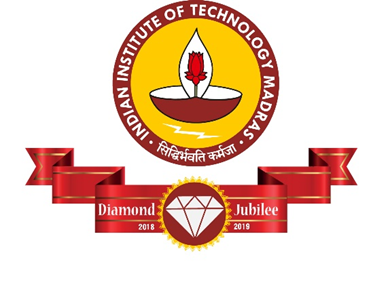

**COURSE CODE: EE5175 (ISP)**

**Under the guidance of **

**Prof. A.N.Rajagopalan**

By 

**EE21S048**

Ms (2021)– EE1

## Image mosaicing 

- Image mosaicing is the alignment and stitching of a collection of images having overlapping regions into a single image. 

- In this assignment, we have been given three images which were captured by panning the scene left to right. These images (img1.png, img2.png and img3.png) capture overlapping regions of the same scene from different viewpoints. 

- The task is to determine the geometric transformations (homographies) between these images and stitch them into a single image

clear;
img1 = imread('s1.jpg');
img2 = imread('s2.jpg');
img3 = imread('s3.jpg');
img1=rgb2gray(img1);
img2=rgb2gray(img2);
img3=rgb2gray(img3);

- Take img2.png as the reference image. 

- Determine homography H21 between  img2.png and  img1.png such that $\mathrm{img1}=H_{21} *\mathrm{img2}$

- Determine homography H23 between  img2.png and  img3.png such that $\mathrm{img3}=H_{21} *\mathrm{img2}$. 

To Compute the homography:

First we get the sift corresponding points and compute the homograohy.

### **Determining homography between two images:**

**Steps:**

**1.**Determine SIFT features of the two images and determine correspondences between them. File sift_corresp.m returns the SIFT correspondences between two images . Now to find H such that: 


$$\left\lbrack \begin{array}{c}
x_i^{\prime } \\
y_i^{\prime } \\
1
\end{array}\right\rbrack =H*\left\lbrack \begin{array}{c}
x_i \\
y_i \\
1
\end{array}\right\rbrack$$


**2**.Run RANSAC on matched points (correspondences) to remove outliers (wrong matches), and the                      homography between the two images.

%% RANSAC Parameters - stricter conditions used than mentioned 
epsilon = 5;
fraction = 0.8;
n_iters = 100; % n_iters  = 10^8 is never used. It converges almost always in the first
               % attempt or at worst, within the first 4-5 attempts
n_samples = 4; 

RANSAC:

%% H21 Matrix
[corresp1, corresp2] = sift_corresp('s1.jpg','s2.jpg');

Finding keypoints... 
2884 keypoints found. 
Finding keypoints... 
3184 keypoints found. 


H21 = finding_H(corresp2, corresp1, epsilon, fraction, n_samples, n_iters);
%% H23 Matrix
[corresp2, corresp3] = sift_corresp('s2.jpg','s3.jpg');

Finding keypoints... 
3184 keypoints found. 
Finding keypoints... 
3538 keypoints found. 


H23 = finding_H(corresp2, corresp3, epsilon, fraction, n_samples, n_iters);

Calculate the image sizes:

%% Image sizes
[width1, height1] = size(img1);
[width2, height2] = size(img2);
[width3, height3] = size(img3);
% x1=x2=x3 and y1=y2=y3
x = width1;
y = height1;
%x,y =360 obtained

Zero padding for Bilinear Interpolation: 

%% Zero pad images for Bilinear Interpolation
temp = zeros(width1+2, height1+2);
temp(2:width1+1, 2:height1+1) = img1;
im1 = temp;
temp = zeros(width2+2, height2+2);
temp(2:width2+1, 2:height2+1) = img2;
im2 = temp;
temp = zeros(width3+2, height3+2);
temp(2:width3+1, 2:height3+1) = img3;
im3 = temp;
clear temp;

### **3. **Creating the mosaic

- Create an empty canvas. 

- For every pixel in the canvas, and corresponding points in img1, img2 and img3 using H21, identity matrix and H23 respectively (target-to-source mapping). 

%% Build canvas
canvas = zeros(width1+width2+width3, height1+height2+height3);
%Offset
c_width=width1+width2+width3

c_width = 1152

c_height=height1+height2+height3

c_height = 2046

offset_row = ceil(c_width/3);
offset_column = ceil(c_height/3);

%% Stitch Images
% Use the pseudo code as given in the assignment PDF
for x_c= 1:c_width
    for y_c= 1:c_height        
        xt = x_c-offset_row;
        yt = y_c-offset_column;  
        vec = [xt; yt; 1];

        %corresponding 2d points in img1
        x_prime = H21*vec;
        x_prime = x_prime(1:2)./x_prime(3);
        xs1 = x_prime(1);
        ys1= x_prime(2);

        %corresponding 2d points in img3
        x_prime = H23*vec;
        x_prime = x_prime(1:2)./x_prime(3);
        xs3 = x_prime(1);
        ys3= x_prime(2);

- Blend the three values by averaging them

- Employ the values in blending only if it falls within the corresponding image bounds. Choose the origin so as to get a full mosaic.

        [intensity1, range1] = bilinear_interpolate(im1, xs1, ys1);
        [intensity2, range2] = bilinear_interpolate(im2, xt, yt);
        [intensity3, range3] = bilinear_interpolate(im3, xs3, ys3);
 
        %intensity1, intensity2,intensity3 are the intensity values 
        %returned by the bilinear interpolation
        %If the requested (xs, ys) lies within the source image canvas then 
        % range1 or range2 or range3= 1
        
        range = range1+range2+range3;       
        intensity = 0;
        if range1>0
            intensity = intensity+intensity1;
        end
        if range2>0
            intensity = intensity+intensity2;
        end
        if range3>0
            intensity = intensity+intensity3;
        end

        if range>0
            intensity = intensity/range; %(averaging the intensity)
        end
        
        canvas(x_c, y_c) = intensity; %intensity is assigned to the target canvas.
    end
end

####  Display the image:

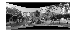

canvas = uint8(canvas);
canvas = canvas(260:860, 350:1750);
imshow(canvas)
title("Images stitched together");

Image1: Lab-o3

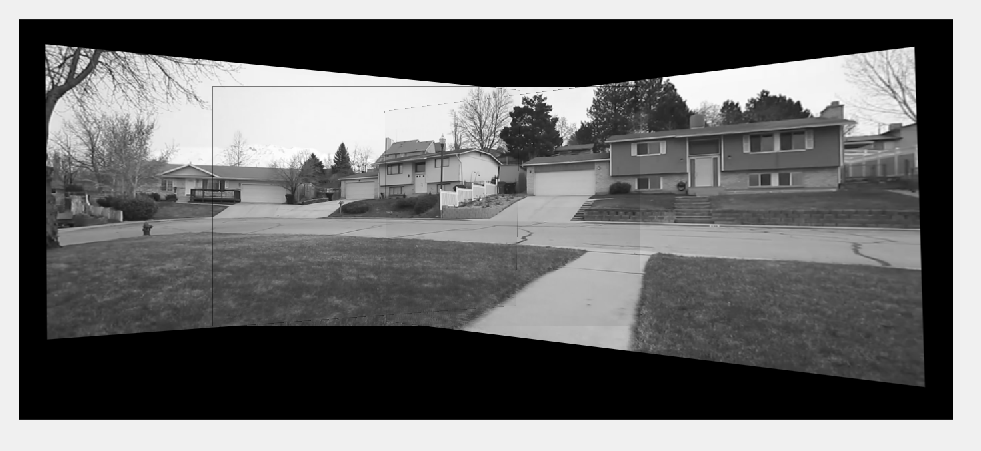 

Image2: ESB lab:306

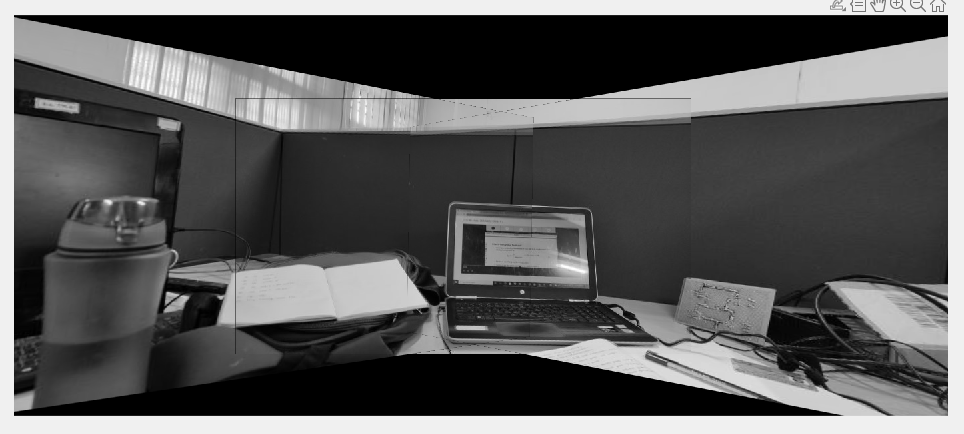

Image3: Velachary gate road, Campus 

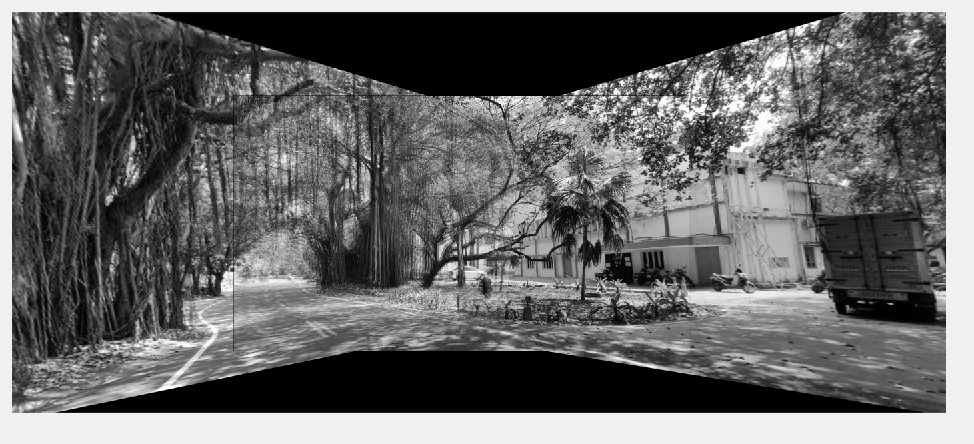

Image4: Academic Block, Campus

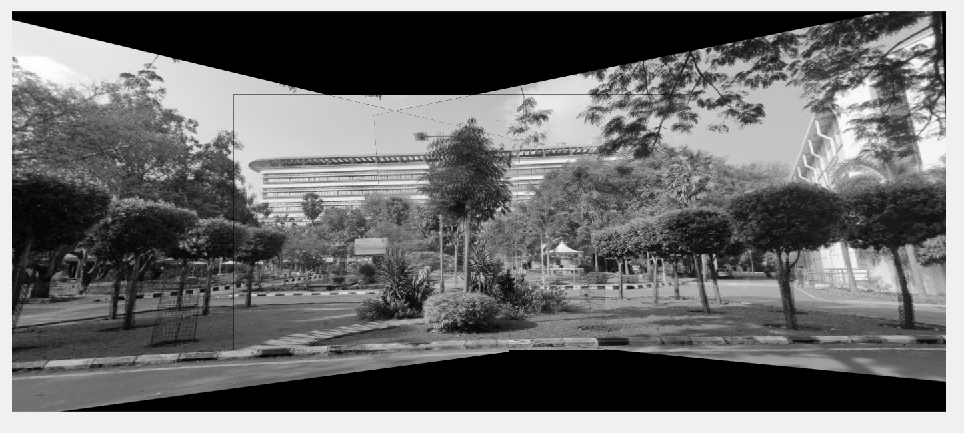

**Conclusion:**

- Thus, alignment and stitching of the images having overlapping regions into a single image is done.

**Bilinear Interpolation function:**

function [intensity_val, in_canvas] = bilinear_interpolate(img, x, y)
    
    [width,height] = size(img); % shape of the zero padded image    
    width = width-2;            % get the shape of the original image
    height = height-2;
    x = x+1;                    % +1 as we are taking coordinates with respect to a zero padded image
    y = y+1;
    x_prime= floor(x);
    y_prime = floor(y);
    a = x-x_prime;
    b = y-y_prime;

    if x_prime >= 1 && x_prime <= width+1 && y_prime >= 1 && y_prime <= height+1
        intensity_val = (1-a)*(1-b)*img(x_prime, y_prime) ...
            + (1-a)*b*img(x_prime, y_prime+1) ...
            + a*(1-b)*img(x_prime+1, y_prime) ...
            + a*b*img(x_prime+1, y_prime+1);
        % If the requested (xs, ys) lies within the source image canvas
        % set within_canvas = 1
        in_canvas = 1;
    else
        intensity_val = 0;
        in_canvas = 0;
    end

end